% Set preferences
set(0,'DefaultAxesXGrid','on','DefaultAxesYGrid','on')

## Building a Reference Model

The requirements on the reference model are: 

- 
$$T_S < 1s$$


- 
$$S_\% < 25 \%$$


These translate into $\zeta > 0.4 $ and $\omega > 12.5 \ rad/s$

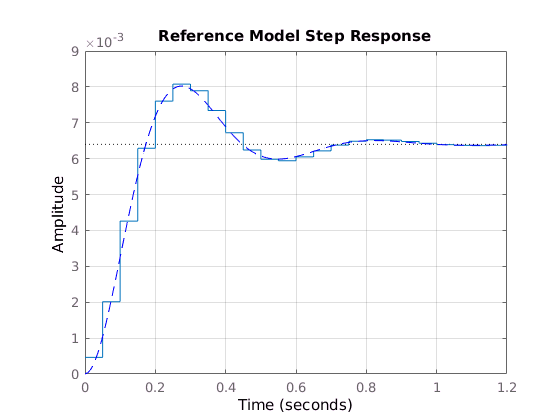

[num, den] = ord2(12.5, 0.4);
RefModel = tf(num, den);
    
% discretize the model
Ts = .05;
RefModel_dt = c2d(RefModel, Ts, 'tustin');
RefModel_dt.Variable = 'z^-1';

mr_step = figure();
    step(RefModel_dt, RefModel, '--'); 

    title({'Reference Model Step Response'});

Note: the reference model has a very low static gain. ($6.4 \cdot 10^{-3}$). We may have to compensate it later on. 

## Reference Model vs. Plant Model

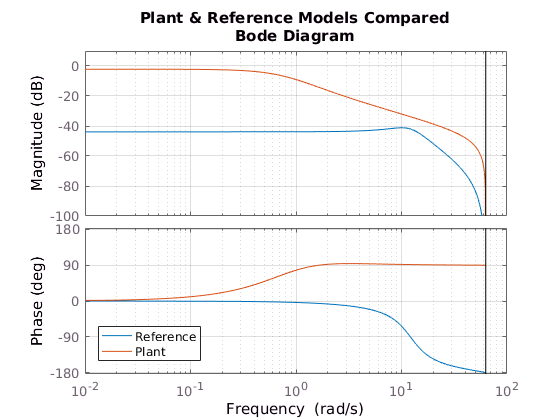

io_data    = load('data/dati_qr');
model_data = load('data/modello');

PlantModel = ss(model_data.A, model_data.B, model_data.C, model_data.D);
PlantModel_dt = c2d(tf(PlantModel), Ts, 'tustin');
PlantModel_dt.Variable = 'z^-1';

fh = figure();
    bode(RefModel_dt, PlantModel_dt); 
    title({'Plant & Reference Models Compared', 'Bode Diagram (Open Loop)'});
    legend('Reference Model', 'Plant', 'location', 'southWest'); 
    
% cut off the lower part of the magnitude graph
fh.Children(4).YLim = [-100, 10];

## Controller Family

The chosen controller family for this project is a simple PID. Since the optimal controller is obtained as : 


$$C(z) = \beta^T \theta^T$$


The controller must be split into its individual components.

ControllerFamily = [
    tf(1, 1); tf(1, [1, 0]); tf([1, 0], 1)  
];

ControllerFamily_dt = c2d(ControllerFamily, Ts, 'tustin');
ControllerFamily_dt.Variable = 'z^-1';

## Perform VRFT

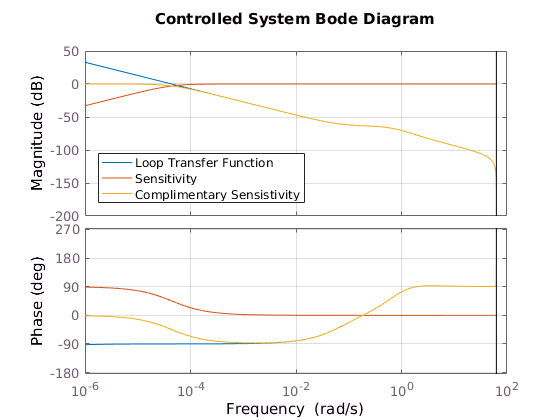

OptimalController_dt = VRFT1_ry(io_data.u1, io_data.y1, RefModel_dt, ControllerFamily_dt, [], [], []);

SensitivityFunctions = loopsens(PlantModel_dt, OptimalController_dt);

bode(SensitivityFunctions.Li, SensitivityFunctions.Si, SensitivityFunctions.Ti);
grid on;

% Draw the legend on the magnitude graph since that is where we have the most empty space
axes = findall(gcf, 'type', 'axes');
legend(axes(3), 'Loop Transfer Function', 'Sensitivity', ...
    'Complimentary Sensistivity', 'location', 'southWest');
title({'Controlled System Bode Diagram'});
axes(3).Title.String = '';

## Compare Reference Model and Closed Loop performance

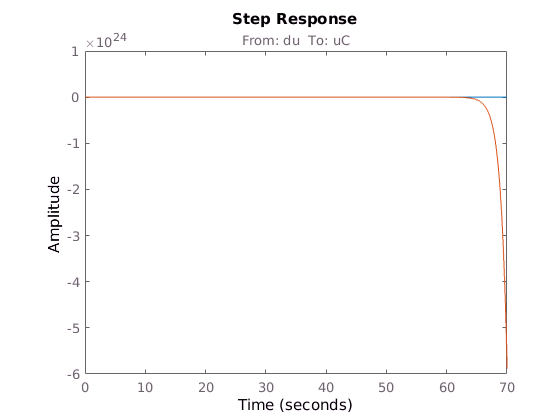

ClosedLoop_dt = SensitivityFunctions.Ti;
step(RefModel_dt, ClosedLoop_dt);